# Bipedal Leg Simulation

#### Import the Arrays of Angles from Python

 
clear
clc


 
py.importlib.reload(py.importlib.import_module('getFrames'));

Arrays Imported!



% Import the Python module
py.importlib.import_module('getFrames');
framesPy = py.getFrames.getRawAngles();

% Initialize empty cell array to store angles
angles_cell1 = cell(length(framesPy), 1);
angles_cell2 = cell(length(framesPy), 1);

% Iterate through each sublist in 'framesPy'
for i = 1:length(framesPy)
    % Extract the third and fourth elements from the current sublist
    hip1 = double(framesPy{i}(3));
    knee1 = double(framesPy{i}(4));
    hip2 = double(framesPy{i}(7));
    knee2 = double(framesPy{i}(8));

    % Store the angles vertically in the cell arrays
    angles_cell1{i,1} = {hip1, knee1};
    angles_cell2{i,1} = {hip2, knee2};
end

disp("Arrays Imported!")

Arrays Imported!


%fprintf('Number of frames: %d\n', length(framesPy));
% Print out contents of angles_cell1 and angles_cell2 side by side
disp('angles_cell1:     angles_cell2:');

angles_cell1:     angles_cell2:


for i = 1:numel(angles_cell1)
    cell1_str = cellfun(@num2str, angles_cell1{i}, 'UniformOutput', false);
    cell2_str = cellfun(@num2str, angles_cell2{i}, 'UniformOutput', false);
    disp([sprintf('%4s', cell1_str{:}),'          ', sprintf('%4s', cell2_str{:})]);
end

   0  90             0   0
 -60  90             0   5
 -45  40            30  20
 -30   0            30  60
   0   0             0  90
   0   5           -60  90
  30  20           -45  40
  30  60           -30   0


## Dual Leg Simulation


%%%%%% make angles cell %%%%%% {hip, knee}
%% red
angles_cell1 = {
    {0, 90};       %frame 1
    {-60, 90};      %frame 2
    {-45, 40};      %frame 3
    {-30, 0};        %frame 4
    {0,0};          %frame 5
    {0, 5};        %frame 6
    {30, 20};     %frame 7
    {30, 60}      %frame 8
};

%%% pink
angles_cell2 = {
    {0,0};          %frame 1
    {0, 5};        %frame 2
    {30, 20};     %frame 3
    {30, 60};     %frame 4
    {0, 90};       %frame 5
    {-60, 90};      %frame 6
    {-45, 40};      %frame 7
    {-30, 0}         %frame 8
};



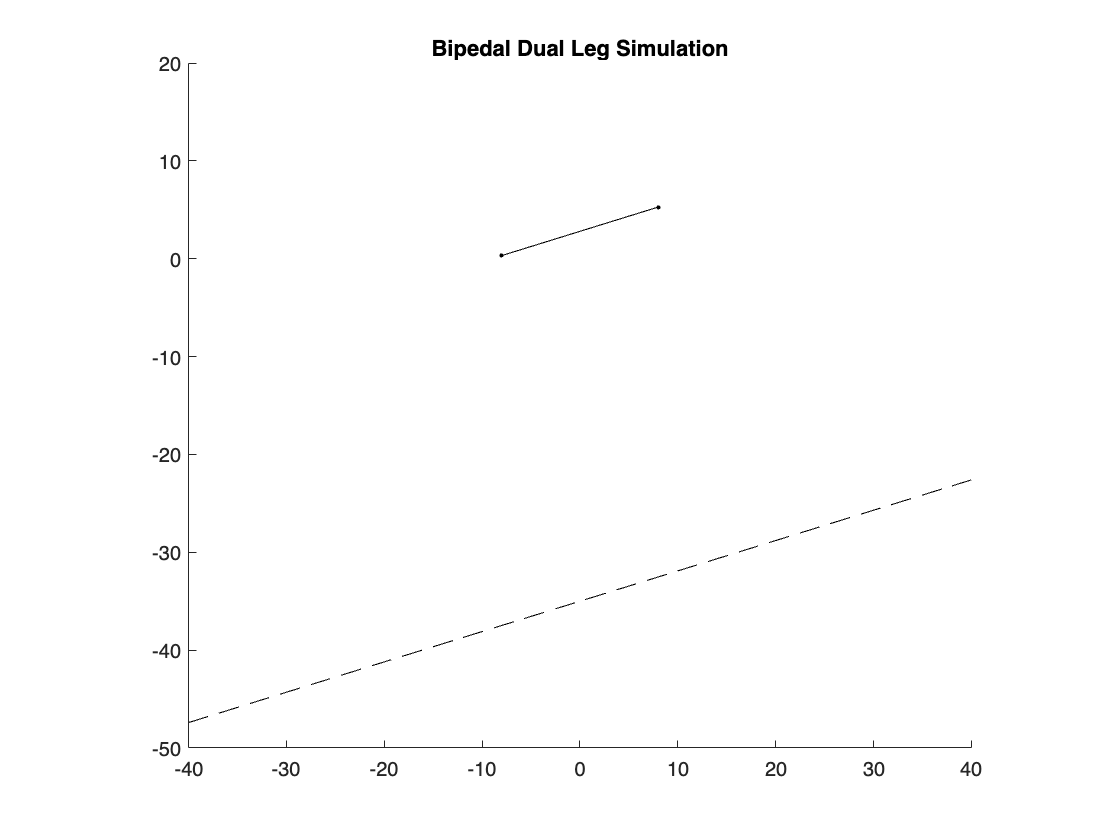

 

%%%%%% LOOP THROUGH %%%%%
figure;
axis equal;
axis manual;
axis([-40 40 -50 20]);

title('Bipedal Dual Leg Simulation');
% Define floor line
x_range1 = [-40, 40];
y_values1 = (0.31) * x_range1 + (-35);
hold on;
plot(x_range1, y_values1, 'k--'); % Floor line
x_range2 = [-8, 8];
y_values2 = (0.31) * x_range2 + (2.8);
plot(x_range2, y_values2, 'k.-'); % Body line

% Set the axis limits after plotting the floor line
xlim([-40 40]);
ylim([-50 20]);

%%%%%% LOOP THROUGH %%%%%
start_hip_angle1 = 0;
start_knee_angle1 = 0;
start_hip_angle2 = 0;
start_knee_angle2 = 0;

angular_velocity = 5;  %[deg/sec]???
num_loop = 2;

for k = 1 : num_loop
    f = 1; % frame #
    for i = 1 : size(angles_cell1,1)
        % Get the angles from the cell array
        angles1 = angles_cell1{i};
        angles2 = angles_cell2{i};
    
        %%%%%%% UNCOMENT IF CALLING FUNCTION FOR ANGLES %%%%%%%%
        %angles = converted_angles_cell{i};
        %goal_hip_angle1 = motor2deg(angles(3));
        %goal_knee_angle1 = motor2deg(angles(4));
        %goal_hip_angle2 = motor2deg(angles(7));
        %goal_knee_angle2 = motor2deg(angles(8));
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
        %%%%%%% UNCOMENT IF MAKING OWN ANGLE CELL ARRAY %%%%%%%%
        goal_hip_angle1 = angles1{1};
        goal_knee_angle1 = angles1{2};
        goal_hip_angle2 = angles2{1};
        goal_knee_angle2 = angles2{2};
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        % Make frame label
        frameLabel = sprintf('Frame: %d', f);
        textObject = text(-5, 15, frameLabel, 'FontSize', 12, 'FontWeight', 'bold', 'Color', '#DADADA');
       
        % Call the move2angle function with the extracted angles
        move2angle_dual_leg(start_hip_angle1, start_knee_angle1, goal_hip_angle1, goal_knee_angle1, start_hip_angle2, start_knee_angle2, goal_hip_angle2, goal_knee_angle2, angular_velocity);
    
        % reset start angles
        start_hip_angle1 = goal_hip_angle1;
        start_knee_angle1 = goal_knee_angle1;
        start_hip_angle2 = goal_hip_angle2;
        start_knee_angle2 = goal_knee_angle2;
        
        % reset frame #
        delete(textObject);
        f = f + 1;
    end
end

#### Display to copy and paste :)

 
new_tuples = angles2tuples(angles_cell1, angles_cell2);

[(11, 2048),(12, 2048),(13, 2048),(14, 3071),(21, 2048),(22, 2048),(23, 2048), (24, 2048)],
[(11, 2048),(12, 2048),(13, 1365),(14, 3071),(21, 2048),(22, 2048),(23, 2048), (24, 2104)],
[(11, 2048),(12, 2048),(13, 1536),(14, 2503),(21, 2048),(22, 2048),(23, 2389), (24, 2275)],
[(11, 2048),(12, 2048),(13, 1706),(14, 2048),(21, 2048),(22, 2048),(23, 2389), (24, 2730)],
[(11, 2048),(12, 2048),(13, 2048),(14, 2048),(21, 2048),(22, 2048),(23, 2048), (24, 3071)],
[(11, 2048),(12, 2048),(13, 2048),(14, 2104),(21, 2048),(22, 2048),(23, 1365), (24, 3071)],
[(11, 2048),(12, 2048),(13, 2389),(14, 2275),(21, 2048),(22, 2048),(23, 1536), (24, 2503)],
[(11, 2048),(12, 2048),(13, 2389),(14, 2730),(21, 2048),(22, 2048),(23, 1706), (24, 2048)],


## Single Leg Simulation

 
%%%%%% make angles cell %%%%%% {hip, knee}
angles_cell = {
    {-50, 80}; 
    {-45, 0};
    {40, 5};
    {30, 60};
    {0, 90}
};

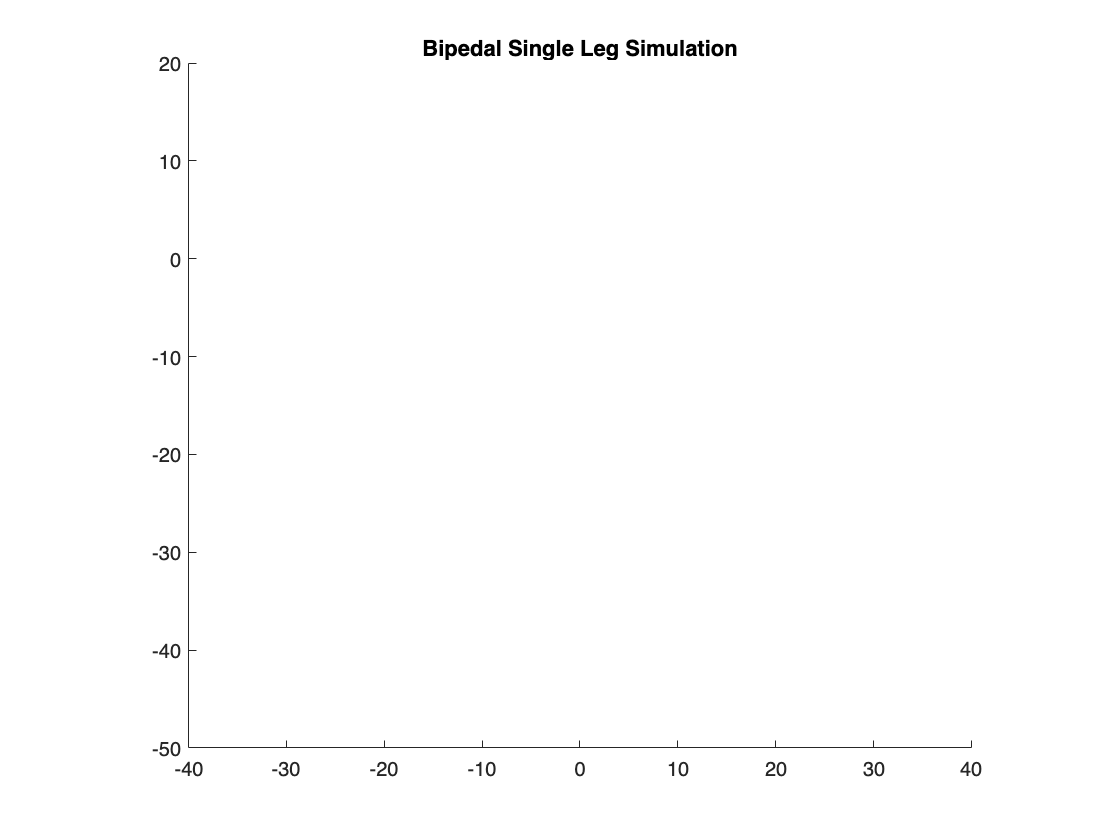

 

figure;
axis equal;
xlim([-40, 40]); % Set the x-axis limits
ylim([-50, 20]); % Set the y-axis limits
title('Bipedal Single Leg Simulation');


%%%%%% LOOP THROUGH %%%%%
start_hip_angle = 0;
start_knee_angle = 0;
angular_velocity = 3;  %[deg/sec]???
num_loop = 3;


for k = 1 : num_loop
    f = 1; % frame #
    for i = 1 : size(angles_cell,1)
        % Get the angles from the cell array
        
        %%%%%%% UNCOMENT IF CALLING FUNCTION FOR ANGLES %%%%%%%%
        %angles = converted_angles_cell{i};
        %goal_hip_angle = motor2deg(angles(3));
        %goal_knee_angle = motor2deg(angles(4));
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
        %%%%%%% UNCOMENT IF MAKING OWN ANGLE CELL ARRAY %%%%%%%%
        angles = angles_cell{i};
        goal_hip_angle = angles{1};
        goal_knee_angle = angles{2};
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        
        % Make frame label
        frameLabel = sprintf('Frame: %d', f);
        textObject = text(5, 0.5, frameLabel, 'FontSize', 12, 'FontWeight', 'bold', 'Color', 'red');
       
        % Call the move2angle function with the extracted angles
        move2angle(start_hip_angle, start_knee_angle, goal_hip_angle, goal_knee_angle, angular_velocity);
    
        % reset start angles
        start_hip_angle = goal_hip_angle;
        start_knee_angle = goal_knee_angle;

        % Replace the text
        delete(textObject);
        f = f + 1;
    end
end